**P.55**

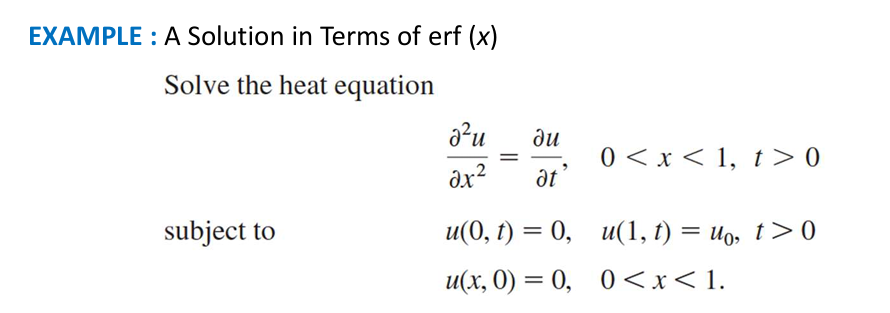

clc;clf;clearvars;
syms x t s u(x,t) U(x,s) u0 Y(x)
Dt = diff(u,t);
D2x = diff(u,x,2);
eqn = laplace(Dt == D2x,t,s)

$$eqn(x) = s\,\mathrm{laplace}\left(u\left(x,t\right),t,s\right)-u\left(x,0\right)=\mathrm{laplace}\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right),t,s\right)$$

cond0 = u(0,t) == 0;
cond1 = u(1,t) == u0;
eqn = subs(eqn,{laplace(u,t,s),u(x,0),laplace(D2x,t,s)},{U(x,s),0,subs(D2x,{u,t},{U,s})})

$$eqn(x) = s\,U\left(x,s\right)=\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond0_s = laplace(cond0,t,s);
cond1_s = laplace(cond1,t,s);
cond0_s = subs(cond0_s,laplace(u(0,t),t,s),U(0,s))

$$cond0\_s = U\left(0,s\right)=0$$

cond1_s = subs(cond1_s,laplace(u(1,t),t,s),U(1,s))

$$cond1\_s = U\left(1,s\right)=\frac{u_{0}}{s}$$

eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s\,Y\left(x\right)=\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond0_s = subs(cond0_s,U,Y)

$$cond0\_s = Y\left(0\right)=0$$

cond1_s = subs(cond1_s,U,Y)

$$cond1\_s = Y\left(1\right)=\frac{u_{0}}{s}$$

sol = dsolve(eqn_n,[cond0_s cond1_s])

$$sol = \frac{u_{0}\,{\mathrm{e}}^{-\sqrt{s}\,x}\,{\mathrm{e}}^{\sqrt{s}}\,\left({\mathrm{e}}^{2\,\sqrt{s}\,x}-1\right)}{s\,\left({\mathrm{e}}^{2\,\sqrt{s}}-1\right)}$$

sol_t = ilaplace(sol,s,t)

$$sol\_t = u_{0}\,\mathrm{ilaplace}\left(\frac{{\mathrm{e}}^{\sqrt{s}-\sqrt{s}\,x}}{s-s\,{\mathrm{e}}^{2\,\sqrt{s}}},s,t\right)-u_{0}\,\mathrm{ilaplace}\left(\frac{{\mathrm{e}}^{\sqrt{s}\,x+\sqrt{s}}}{s-s\,{\mathrm{e}}^{2\,\sqrt{s}}},s,t\right)$$

**Plot solution**

clf
syms n
u0 = 100

u0 = 100

max =10

max = 10

assume(n,{'integer','positive'})
V(x,t) = u0*symsum(erf((2*n+1+x)/(sqrt(4*t)))-erf((2*n+1-x)/(sqrt(4*t))),n,0,inf)

$$V(x, t) = 100\,\left(\sum_{n=0}^{\infty }\left(\mathrm{erf}\left(\frac{2\,n+x+1}{2\,\sqrt{t}}\right)-\mathrm{erf}\left(\frac{2\,n-x+1}{2\,\sqrt{t}}\right)\right)\right)$$

v(x,t) = u0*symsum(erf((2*n+1+x)/(sqrt(4*t)))-erf((2*n+1-x)/(sqrt(4*t))),n,0,max)

$$v(x, t) = 100\,\mathrm{erf}\left(\frac{x-1}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+1}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-3}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+3}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-5}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+5}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-7}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+7}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-9}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+9}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-11}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+11}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-13}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+13}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-15}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+15}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-17}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+17}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-19}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+19}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x-21}{2\,\sqrt{t}}\right)+100\,\mathrm{erf}\left(\frac{x+21}{2\,\sqrt{t}}\right)$$

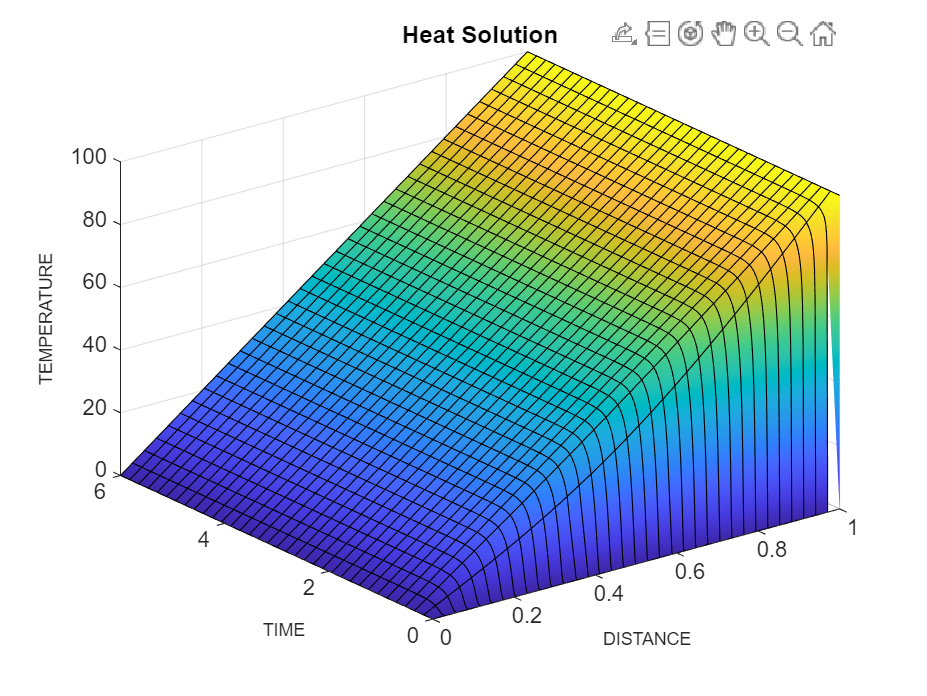

fsurf(v,[0 1 0 6])
title("Heat Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)